Máme naměřená data vyjadřující závislost výšky a váhy lidí. Chceme udělat aproximaci těchto dat, abychom získali rovnici vyjadřující právě tuto závislost. Předpokládáme, že závislost bude přímka. 

Rovnice přímky:


$$y=k*x+q$$


kde $k$ ovlivňuje sklon a $q$ zase offset přímky. Naše přímka tedy vypadá následovně:


$$výška=k*váha+q$$
  

kde pro jednoduchost řekneme, že $k=0,64$. 

Máme tedy úlohu pouze s jedním parametrem, který chceme nastavit tak, aby aproximace byla co možná nejlepší. Takže úloha je právě ono hledání vhodného parametru.

Naše naměřená data jsou:


$$\left\lbrack \begin{array}{cccc}
výška & 1,4 & 1,9 & 3,2\\
váha & 0,5 & 2,3 & 2,9
\end{array}\right\rbrack$$


vyska = [1.4 1.9 3.2];
vaha = [0.5 2.3 2.9];
plot(vaha,vyska,"ro");
hold on;

Nejprve si musíme vytvořit tzv. **ztrátovou funkci **$E$ (Loss function). V našem případě se bude jednat o vztah vyjadřující sumu všech kvadratických rozdílů naší aproximované křivky a naměřených dat. Tento vztah se nazývá metoda nejmenších čtverců a je velmi často používána pro hledání aproximace.

#### 
$$\begin{array}{l}
E=\sum_{n_0 }^N {\left(y_{naměřené} -y_{aproximovaé} \right)}^2 \\
E=\sum_{n_0 }^N {\left(y_{naměřené} -\left(k*x_{naměřené} +q\right)\right)}^2 \\
E={\left(1,4-\left(0,64*0,5+q\right)\right)}^2 +{\left(1,9-\left(0,64*2,3+q\right)\right)}^2 {\;+\;\left(3,2-\left(0,64*2,9+q\right)\right)}^2 
\end{array}$$


kde $N$je počet všech naměřených dat, a $q$ je parametr, který hledáme. Takže máme vyčíslenou ztrátovou funkci a mohu začít pátrat po optimálním řešení. Pozor! My neznáme jaká ta minimální hodnota $E$ bude, takže nelze za $E$dosadit prostě třeba hodnotu nula a analiticky dopočítat přesnou hodnotu parametru $q$.  Samozřejmě by nás také mohlo napadnout, za parametr $q$ prostě začít dosazovat náhodné čísla a s trochou štěstí bychom i nějaké jakési minimum této funkce dostali, ale my to uděláme trochu sofistikovaněji pomocí metody největšího spádu (Gradient Decent). 

Ta sofistikovanost bude následující. Využijeme totiž toho, že lokální extrémy funkce mají derivaci rovnou nule. Pokud jsme tedy v minimu naší ztrátové funkce, tak musí být její derivace rovna nule. Zde by mohl nastat problém, pokud by ztrátová funkce obsahovala více lokálních extrémů, ale jelikož je naše ztrátová funkce kvadrát odchylek, čili parabola, tak víme, že parabola obsahuje lokální extrém pouze jeden a to globální minimum, které se právě snažíme nalézt. 

Takže provedeme derivaci naší ztrátové funkce podle parametru $q$. Derivace ztrátové funkce je rovna derivaci všech jednotlivých členů sumy, tím pádem:

#### 
$$\frac{\partial E}{\partial q}=\sum_{n_0 }^N \frac{{\partial \left(y_{naměřené} -\left(k*x_{naměřené} +q\right)\right)}^2 }{\partial q}=\sum_{n_0 }^N 2\left(y_{naměřené} -\left(k*x_{naměřené} +q\right)\right)*-1=\sum_{n_0 }^N -2\left(y_{naměřené} -\left(k*x_{naměřené} +q\right)\right)$$


#### 
$$\frac{\partial E}{\partial q}=\frac{{\partial \left(1,4-\left(0,64*0,5+q\right)\right)}^2 }{\partial q}+\frac{{\partial \left(1,9-\left(0,64*2,3+q\right)\right)}^2 }{\partial q}+\;\frac{{\partial \left(3,2-\left(0,64*2,9+q\right)\right)}^2 }{\partial q}$$


#### 
$$\frac{\partial E}{\partial q}=$$

$$-2\left(1,4-\left(0,64*0,5+q\right)\right)+-2\left(1,9-\left(0,64*2,3+q\right)\right)+-2\left(3,2-\left(0,64*2,9+q\right)\right)$$


Derivace složené funkce je derivace vnitřní funkce krát derivace vnější funkce, takže výsledek je vidět výše. Takže nyní máme připravenou derivaci ztrátové funkci a můžeme začít hledat minimum. Nejdříve si zvolíme náhodnou hodnotu našeho parametru $q$. např. $q=0$ a následně zjistíme, jakou má ztrátová funkce v tomto bodě hodnotu derivace pouhým dosazením za parametr $q$. Pokud hodnota derivace v tomto bodě není nulová, tak bychom potřebovali změnit hodnotu $q$ tak, aby jsme se k minimu přiblížili. Otázka nyní zní, zda parametr zvyšovat či snižovat a o kolik. Odpoveď na tuto otázku nám dá výsledek, který jsme získali dosazením parametru $q$ do derivace ztrátové funkce. Hodnota derivace nám totiž říká, zda ztrátová funkce v tomto bodě roste (kladná hodnota derivace), nebo kelsá (záporná hodnota derivace) a velikost této hodnoty také odpovídá tomu jak rychle hodnota klesá, či roste. Takže nyní musíme ve směru (pokud ztrátová funkce v tomto bodě klesá, tak parametr zvyžuji a pokud naopak roste, tak parametr zvyšuji) upravit parametr. K jeho úpravě použijeme ještě přenásobení spočtené hodnoty derivace v daném bodě tzv. koeficientem učení $\alpha$. Koeficient učení $\alpha$ nám ovlivňuje "velikost kroku" z daného bodu do nového. Pokud volíme koeficient učení příliš malý, metodě bude déle trvat, než ke správné hodnotě dokonverguje. Pokud naopak volíme koeficient učení příliš velký, může se nám naopak stát, že metoda bude dokonce divergovat (krok se provede přes minimum do hodnoty ztrátové funcke ještě vyšší, než byla v bodě, ze kterého jsme výpočet prováděli). Koeficient učení lze zvolit tedy např. $\alpha \;=0,1$. 

Zkusme si tedy dosadit "náhodný" počáteční bod pro naše odvození derivace ztrátové funkce výše. 

####  
$$\frac{\partial E}{\partial q}=$$

$$-2\left(1,4-\left(0,64*0,5+0\right)\right)+-2\left(1,9-\left(0,64*2,3+0\right)\right)+-2\left(3,2-\left(0,64*2,9+0\right)\right)=-5,7$$


Výsledkem je $-5,7$, čili víme, že musíme hodnotu parametru snížit. Koeficient učení zvolíme oněch $0,1$, tím pádem parametr nakonec bude mít hodnotu:

#### 
$$q_{\mathrm{nový}} =q_{\mathrm{původní}} -\left(\frac{\partial E}{\partial q}*\alpha \right)$$


#### 
$$q_{\mathrm{nový}} =0-\left(\left(-5,7\right)*0,1\right)$$


#### 
$$q_{\mathrm{nový}} =0,57$$


Tímto výpočtem jsem tedy získal novou hodnotu parametru $q$. Novou hodnotu opět dosadíme do odvozené derivace ztrátové funkce a zjistíme, jestli se již rovná nule. Pokud ano, výpočet je u konce a my našli optimální hodnotu parametru $q$. Pokud ale gradient není nulový, tak stejným způsobek jako výše upravíme parametr $q$. Tento proces provádíme tak dlouho, dokud parametr $q$ nebude roven nule. Přesněji řečeno se málo kdy povede nalézt přesně nulovou derivaci ztátové funkce, proto typicky volíme určitou toleranci $\tau$, při které nám již přesnost aproximace stačí. Tato tolerance může být v našem příkaldu třeba $\tau \;=0,01$.

Výpočtem bychom dostali hodnoty parametrů:

#### 
$$\begin{array}{l}
q_{\mathrm{náhodný}} =0\\
q=0,57\\
q=0,8\;\\
q=0,89\\
q=0,94\\
q=0,95
\end{array}$$


Při hodnotě parametru $q=0,95$ je již derivace ztrátové funkce pouze $-0,004$. To znamená, že derivace ztrátové funkce je téměř nulová (menší než naše zvolená tolerance $0,01$). Tím pádem mohu výpočet ukončit a hodnotu parametru $q$ považovat za správnou.

Teď to celé zkusíme naházet do kódu. Data z tabulky máme již připravené z kódu nahoře, takže zde připravím jen symbolickou proměnou parametru $q$, koeficient učení $\alpha$ a toleranci $\tau$ 

alpha = 0.1;
tau = 0.01;
syms q_sym;

Nyní si vyjádříme ztrátovou funkcí ve tvatu metody nejmenších čtverců.

E_sym = sum((vyska - (vaha*0.64 + q_sym)).^2);

 A ztrátovou funkci derivujeme.

dE_sym = diff(E_sym,q_sym);

Nyní si ještě naplníme první parametr náhodnou hodnotou, v našem případě nulou. Pro jméno koeficientu zvolíme odlišné jméno, než pro jméno symbolické jméno koeficientu, aby nám program fungoval.

q = 0;

V tuhle chvíli mám vše co je potřeba, takže mohu iteračně provádět hledání nových a stále přesnějších parametrů $q$, dokud nebude dosažena požadovaná přesnost, nebo dokud nebude dosaženo maximálního počtu iterací. V našem případě jsme zvolili maximální počet iterací $\mathrm{100}$.

for i = 1:100 
    dE = (double(subs(dE_sym,q_sym,q)));
    if abs(dE) < tau
        break;
    end
    q = q - dE*alpha
end

Zkusíme si aproximaci vykreslit do grafu.

plot(vaha,0.64.*vaha + q,"b-");
hold off;

To by asi šlo. Pro zajímavost je možné si vykreslit ještě graf ztrátové funkce, a derivace ztrátové funkce.

plot(0:0.1:2,double(subs(E_sym,q_sym,0:0.1:2)));
grid on;

Z grafu ztrátové funkce je patrné, že se jedná skutečně o parabolu, jak jsme předpokládali. je také vidět, že minimum má zhruba okolo těch $0,95$. Takže i výsledek naší optimalizace parametru byl úspěšný.

plot(0:0.1:2,double(subs(dE_sym,q_sym,0:0.1:2)));
grid on;

Z grafu derivace ztrátové funkce je pro změnu vidět, že nulové hodnoty skutečně dosahuje při oněch zhruba $0,95$ a také že pokud by parametr byl větší, tak hodnota derivace byla kladná (to by značilo, že hodnotu parametru musím snižovat) a naopak pro hodnoty menší než $0,95$ je derivace záporná, čili naznačuje, že pro dosažení nulové derivace musím naopak parametr zvyšovat. 

Tak a teď si přidáme menší komplikaci. Ta komplikace se jmenuje další parametr, konkrétně to bude parametr $k$ z naší rovnice přímky $výška=k*váha+q$. Do téhle doby byl parametr $k$ nastaven stabilně na $0,64$, ale nyní budeme provádět aproximaci na základě obou dvou parametrů zároveň.

V principu vše děláme stejně. Takže začneme vytvořením ztrátové funkce $E\ldotp$

#### 
$$\begin{array}{l}
E=\sum_{n_0 }^N {\left(y_{naměřené} -y_{aproximovaé} \right)}^2 \\
E=\sum_{n_0 }^N {\left(y_{naměřené} -\left(k*x_{naměřené} +q\right)\right)}^2 \\
E={\left(1,4-\left(k*0,5+q\right)\right)}^2 +{\left(1,9-\left(k*2,3+q\right)\right)}^2 {\;+\;\left(3,2-\left(k*2,9+q\right)\right)}^2 
\end{array}$$


Vidíme že vztah pro ztrátovou funkci je naprosto stejný, jen s rozdílem, že místo konstantní hodnoty $0,64$ je nyní parametr $k$. 

Následuje derivace, ale nyní máme dva parametry, takže budeme dělat nejdříve parciální derivaci podle parametru $q$ a poté parciální derivaci podle parametru $k$. To znamená, že získám dva vztahy. Jeden vyjadřující závislost na parametru $q$, kterým budu následně tento parametr upravovat a druhý vyjadřující závislost na parametru $k$, který bude zase použit pro úpravu parametru $k$. Jinými slovy jsem vlatně spočítal gradient ztrátové funkce s ohledem na všechny její parametry. Proto se metoda jmenuje gradientní.  


$$\nabla E=\left(\frac{\partial E}{\partial q},\frac{\partial E}{\partial k}\right)$$


Parciální derivace podle parametru $q$:

#### 
$$\frac{\partial E}{\partial q}=\sum_{n_0 }^N \frac{{\partial \left(y_{naměřené} -\left(k*x_{naměřené} +q\right)\right)}^2 }{\partial q}=\sum_{n_0 }^N 2\left(y_{naměřené} -\left(k*x_{naměřené} +q\right)\right)*-1=\sum_{n_0 }^N -2\left(y_{naměřené} -\left(k*x_{naměřené} +q\right)\right)$$


#### 
$$\frac{\partial E}{\partial q}=\frac{{\partial \left(1,4-\left(k*0,5+q\right)\right)}^2 }{\partial q}+\frac{{\partial \left(1,9-\left(k*2,3+q\right)\right)}^2 }{\partial q}+\;\frac{{\partial \left(3,2-\left(k*2,9+q\right)\right)}^2 }{\partial q}$$


#### 
$$\frac{\partial E}{\partial q}=$$

$$-2\left(1,4-\left(k*0,5+q\right)\right)+-2\left(1,9-\left(k*2,3+q\right)\right)+-2\left(3,2-\left(k*2,9+q\right)\right)$$


Parciální derivace podle parametru $k$:

#### 
$$\frac{\partial E}{\partial k}=\sum_{n_0 }^N \frac{{\partial \left(y_{naměřené} -\left(k*x_{naměřené} +q\right)\right)}^2 }{\partial k}=\sum_{n_0 }^N 2\left(y_{naměřené} -\left(k*x_{naměřené} +q\right)\right)*-x_{naměřené} =\sum_{n_0 }^N -2{*x}_{naměřené} *\left(y_{naměřené} -\left(k*x_{naměřené} +q\right)\right)$$


#### 
$$\frac{\partial E}{\partial k}=\frac{{\partial \left(1,4-\left(k*0,5+q\right)\right)}^2 }{\partial k}+\frac{{\partial \left(1,9-\left(k*2,3+q\right)\right)}^2 }{\partial k}+\;\frac{{\partial \left(3,2-\left(k*2,9+q\right)\right)}^2 }{\partial k}$$


#### 
$$\frac{\partial E}{\partial k}=$$

$$-2*0,5*\left(1,4-\left(k*0,5+q\right)\right)+-2*2,3*\left(1,9-\left(k*2,3+q\right)\right)+-2*2,9*\left(3,2-\left(k*2,9+q\right)\right)$$


Nyní, když máme gradienty úspěšně spočteny, tak můžeme postupovat zase obdobně, jako u výpočtu s jedním parametrem. To znamená, že si pro každý parametr náhodně určím hodnoty. U nás to bude $q=0$ a $k=1$. Hodnoty dosadím gradientu ztrátové funkce, čili do obou vztahů získaných pomocí parciálních derivací ztrátové funkce. 

#### 
$$\frac{\partial E}{\partial q}=-2\left(1,4-\left(1*0,5+0\right)\right)+-2\left(1,9-\left(1*2,3+0\right)\right)+-2\left(3,2-\left(1*2,9+0\right)\right)=-1,6$$


#### 
$$\frac{\partial E}{\partial k}=$$

$$-2*0,5*\left(1,4-\left(1*0,5+0\right)\right)+-2*2,3*\left(1,9-\left(1*2,3+0\right)\right)+-2*2,9*\left(3,2-\left(1*2,9+0\right)\right)=-0,8$$


S hodnotami získnými těmito dosazeními zacházím stejně jako u příkaldu s jedním parametrem. Čili hodnoty přenásobím koeficientem učení a odečítám je od původních hodnot koecicientů. **Pozor! **V tomto případě by již výpočet nefungoval pro hodnotu koeficientu učení $\alpha =0\ldotp 1$. Optimalizace těchto dvou parametrů najednou si žádá nižší krok, aby dokonvergovala k požadovanému optimu. Zvolíme tedy krok $0,01$.

#### 
$$q_{\mathrm{nový}} =q_{\mathrm{původní}} -\left(\frac{\partial E}{\partial q}*\alpha \right)$$


#### 
$$q_{\mathrm{nový}} =0-\left(\left(-1,6\right)*0,01\right)$$


#### 
$$q_{\mathrm{nový}} =0,016$$


#### 
$$q_{\mathrm{nový}} =q_{\mathrm{původní}} -\left(\frac{\partial E}{\partial k}*\alpha \right)$$


#### 
$$q_{\mathrm{nový}} =1-\left(\left(-0,8\right)*0,01\right)$$


#### 
$$q_{\mathrm{nový}} =1,008$$


Postup zase opakujeme tak dlouho, dokud nebude křivka aproximovaná podle naší zadané tolerance.

Takže to pojďme převést do kódu. Data z tabulky máme stále připravené z kódu nahoře, takže zde připravím jen symbolické proměnné parametrů $q,k$, koeficient učení $\alpha$ a toleranci $\tau$ 

alpha = 0.01;
tau = 0.01;
syms q_sym k_sym;

Nyní si vyjádříme ztrátovou funkcí ve tvatu metody nejmenších čtverců.

E_sym = sum((vyska - (vaha*k_sym + q_sym)).^2);

 A ztrátovou funkci derivujeme. Můžeme buď derivovat jednotlivé členy zvlášť, nebo využít funkce gradient.

%        buď takhle:
% dEdq_sym = diff(E_sym,q_sym);
% dEdk_sym = diff(E_sym,k_sym);
%        nebo takhle:
grad_E_sym = gradient(E_sym,[q_sym,k_sym]);

Nyní si ještě naplníme první parametr $q$ a $k$ náhodnými hodnotami, v našem případě $q=0,\;k=1$.

q = 0;
k = 1;

V tuhle chvíli mám vše co je potřeba, takže mohu iteračně provádět hledání nových a stále přesnějších parametrů $q$ a $k$, dokud nebude dosažena požadovaná přesnost, nebo dokud nebude dosaženo maximálního počtu iterací. V našem případě jsme zvolili maximální počet iterací $100$.

for i = 1:500 
    dEdq = (double(subs(grad_E_sym(1),[q_sym,k_sym],[q,k])));
    dEdk = (double(subs(grad_E_sym(2),[q_sym,k_sym],[q,k])));
    
    if (abs(dEdq) < tau) && (abs(dEdk) < tau)
        iter = i;
        break;
    end
    q = q - dEdq*alpha;
    k = k - dEdk*alpha;
end

Zkusíme si aproximaci vykreslit do grafu.

plot(vaha,vyska,"ro");
hold on;
plot(vaha,k.*vaha + q,"b-");
hold off;

To by asi taky šlo. Pro zajímavost je možné si vykreslit ještě graf ztrátové funkce, a derivace ztrátové funkce.

fsurf(E_sym,[0 2 0 2]);
grid on;

Na první pohled je vidět, že se jedná o 3D graf, neboď vyobrazuj ztrátovou funkci v závislosti na dvou parametrech a to $q$ a $k$.

fsurf(grad_E_sym(1),[0 2 0 2]);
fsurf(grad_E_sym(2),[0 2 0 2]);
grid on;

Při vykreselní gradientu ztrátové funkci musíme vykreslit každou parciální derivaci zvlášť. První odpovídá parciální derivaci ztrátové funcke podle parametru $q$ a druhý zase parciální derivaci ztrátové funkce podle parametru $k$.   

Nevyhnutelná otázka je, co kdybych měl parametrů víc než dva? Např bych chtěl zadaná data proklát polynomem vyšího řádu. Postup je zase naprosto totožný. Parciálních derivací bude stejné množství, jako je parametrů a stejným způsobm optimalizuji. 

 Nejprve si tedy vytvořím parametry, které budu optimalizovat. Jejich počet je odvozen od řádu polynomu, kterým chci aproximovat.

alpha = 0.0000001;
tau = 0.01;
M = 3;
syms w_sym [1,M+1];

Data která jsem fitoval přímkou se mi teď nehodí, jelikož je jich málo, vytvořím si tedy jiná data. Konkrétně si nechám vygenerovat nějaký polynom čtvrtého řádu a proložím ho gausovským šumem.

func = @(x) (x.^3)+(2.*x.^2)+(-3.*x)+5;
from = -5;   
to = 5;    

N =  20;                            % počet vzorků
x = from:((to-from)/(N-1)):to;      % vzorkovací čas
y = awgn(func(x),2);               % generátor naměřených dat

Teď musím napsat zjistit ztrátovou funkci, ale k tomu potřebuju mít nadefinovaný předpis polynomu, pro který ztrátovou funkci počítám. To zajišťuje následující kód:

y_sym = sym(0);
syms x_sym;
for j = 0:M                                     % vypočítej přes daný řád polynomu
    y_sym = y_sym + ((w_sym(j+1))*(x_sym^j));   % podle rovnice polynomu (x^j*w_j)
end

V podstatě jsem si jen přopravil vektor $y$ který obsahuje symbolicky všechny koeficienty, ale také symbolicky vstupy.

#### 
$$y=w_1 +w_2 *x+w_3 *x^2 +\;\ldotp \ldotp \ldotp +w_M *x^M \;$$


Nyní můžeme přikročit konečně k vytvoření ztrátové funcke.

E_sym = sum((y-subs(y_sym,x_sym,x)).^2);

A teď přijde na řadu parciální derivace podle všech parametrů $w$. 

grad_E_sym = gradient(E_sym,w_sym);

Nyní všechny koeficienty nastavím na náhodné hodoty od jedné do pěti.

w = (rand(M+1,1)*5);

A nakonec samotný iterační výpočet.

for i = 1:1000 
    grad_E = double(subs(grad_E_sym,w_sym,w'));
    if (abs(max(grad_E)) < tau)
        iter = i;
        break;
    end
    w = w - grad_E*alpha
end

w =     2.4215
    4.2229
    1.0477
    2.7360


w =     2.4216
    4.2216
    1.0484
    2.7109


w =     2.4216
    4.2203
    1.0491
    2.6860


w =     2.4217
    4.2190
    1.0498
    2.6615


w =     2.4217
    4.2177
    1.0505
    2.6372


w =     2.4218
    4.2165
    1.0511
    2.6133


w =     2.4218
    4.2152
    1.0518
    2.5896


w =     2.4219
    4.2140
    1.0525
    2.5662


w =     2.4219
    4.2128
    1.0532
    2.5431


w =     2.4219
    4.2116
    1.0539
    2.5203


w =     2.4220
    4.2104
    1.0546
    2.4977


w =     2.4220
    4.2092
    1.0552
    2.4754


w =     2.4221
    4.2080
    1.0559
    2.4534


w =     2.4221
    4.2069
    1.0566
    2.4316


w =     2.4222
    4.2057
    1.0573
    2.4101


w =     2.4222
    4.2046
    1.0580
    2.3889


w =     2.4223
    4.2035
    1.0587
    2.3679


w =     2.4223
    4.2024
    1.0593
    2.3471


w =     2.4224
    4.2013
    1.0600
    2.3267


w =     2.4224
    4.2002
    1.0607
    2.3064


w =     2.4225
    4.1992
    1.0614
    2.2864


w =     2.4225
    4.1981
    1.0621
    2.2666


w =     2.4226
    4.1971
    1.0627
    2.2471


w =     2.4226
    4.1961
    1.0634
    2.2278


w =     2.4226
    4.1951
    1.0641
    2.2088


w =     2.4227
    4.1941
    1.0648
    2.1899


w =     2.4227
    4.1931
    1.0654
    2.1713


w =     2.4228
    4.1921
    1.0661
    2.1529


w =     2.4228
    4.1911
    1.0668
    2.1348


w =     2.4229
    4.1902
    1.0675
    2.1168


w =     2.4229
    4.1892
    1.0681
    2.0991


w =     2.4230
    4.1883
    1.0688
    2.0816


w =     2.4230
    4.1874
    1.0695
    2.0643


w =     2.4231
    4.1864
    1.0702
    2.0472


w =     2.4231
    4.1855
    1.0708
    2.0303


w =     2.4231
    4.1847
    1.0715
    2.0136


w =     2.4232
    4.1838
    1.0722
    1.9971


w =     2.4232
    4.1829
    1.0729
    1.9808


w =     2.4233
    4.1820
    1.0735
    1.9647


w =     2.4233
    4.1812
    1.0742
    1.9487


w =     2.4234
    4.1803
    1.0749
    1.9330


w =     2.4234
    4.1795
    1.0755
    1.9175


w =     2.4235
    4.1787
    1.0762
    1.9021


w =     2.4235
    4.1779
    1.0769
    1.8870


w =     2.4236
    4.1771
    1.0776
    1.8720


w =     2.4236
    4.1763
    1.0782
    1.8572


w =     2.4237
    4.1755
    1.0789
    1.8426


w =     2.4237
    4.1747
    1.0796
    1.8281


w =     2.4237
    4.1739
    1.0802
    1.8138


w =     2.4238
    4.1732
    1.0809
    1.7997


w = 4×1
    2.4238
    4.1724
    1.0816
    1.7858


w = 4×1
    2.4239
    4.1717
    1.0822
    1.7720


w = 4×1
    2.4239
    4.1709
    1.0829
    1.7584


w = 4×1
    2.4240
    4.1702
    1.0836
    1.7450


w = 4×1
    2.4240
    4.1695
    1.0842
    1.7317


w = 4×1
    2.4241
    4.1688
    1.0849
    1.7186


w = 4×1
    2.4241
    4.1681
    1.0856
    1.7056


w = 4×1
    2.4242
    4.1674
    1.0862
    1.6928


w = 4×1
    2.4242
    4.1667
    1.0869
    1.6801


w = 4×1
    2.4242
    4.1660
    1.0875
    1.6676


w = 4×1
    2.4243
    4.1654
    1.0882
    1.6552


w = 4×1
    2.4243
    4.1647
    1.0889
    1.6430


w = 4×1
    2.4244
    4.1640
    1.0895
    1.6310


w = 4×1
    2.4244
    4.1634
    1.0902
    1.6191


w = 4×1
    2.4245
    4.1627
    1.0909
    1.6073


w = 4×1
    2.4245
    4.1621
    1.0915
    1.5956


w = 4×1
    2.4246
    4.1615
    1.0922
    1.5841


w = 4×1
    2.4246
    4.1609
    1.0928
    1.5728


w = 4×1
    2.4246
    4.1602
    1.0935
    1.5616


w = 4×1
    2.4247
    4.1596
    1.0942
    1.5505


w = 4×1
    2.4247
    4.1590
    1.0948
    1.5395


w = 4×1
    2.4248
    4.1584
    1.0955
    1.5287


w = 4×1
    2.4248
    4.1579
    1.0961
    1.5180


w = 4×1
    2.4249
    4.1573
    1.0968
    1.5074


w = 4×1
    2.4249
    4.1567
    1.0974
    1.4970


w = 4×1
    2.4250
    4.1561
    1.0981
    1.4867


w = 4×1
    2.4250
    4.1556
    1.0988
    1.4765


w = 4×1
    2.4251
    4.1550
    1.0994
    1.4664


w = 4×1
    2.4251
    4.1545
    1.1001
    1.4565


w = 4×1
    2.4251
    4.1539
    1.1007
    1.4466


w = 4×1
    2.4252
    4.1534
    1.1014
    1.4369


w = 4×1
    2.4252
    4.1529
    1.1020
    1.4273


w = 4×1
    2.4253
    4.1523
    1.1027
    1.4178


w = 4×1
    2.4253
    4.1518
    1.1033
    1.4085


w = 4×1
    2.4254
    4.1513
    1.1040
    1.3992


w = 4×1
    2.4254
    4.1508
    1.1047
    1.3901


w = 4×1
    2.4255
    4.1503
    1.1053
    1.3810


w = 4×1
    2.4255
    4.1498
    1.1060
    1.3721


w = 4×1
    2.4255
    4.1493
    1.1066
    1.3633


w = 4×1
    2.4256
    4.1488
    1.1073
    1.3546


w = 4×1
    2.4256
    4.1484
    1.1079
    1.3460


w = 4×1
    2.4257
    4.1479
    1.1086
    1.3375


w = 4×1
    2.4257
    4.1474
    1.1092
    1.3291


w = 4×1
    2.4258
    4.1469
    1.1099
    1.3207


w = 4×1
    2.4258
    4.1465
    1.1105
    1.3125


w = 4×1
    2.4259
    4.1460
    1.1112
    1.3044


w = 4×1
    2.4259
    4.1456
    1.1118
    1.2964


w = 4×1
    2.4259
    4.1451
    1.1125
    1.2885


w = 4×1
    2.4260
    4.1447
    1.1131
    1.2807


w = 4×1
    2.4260
    4.1443
    1.1137
    1.2730


w = 4×1
    2.4261
    4.1438
    1.1144
    1.2653


w = 4×1
    2.4261
    4.1434
    1.1150
    1.2578


w = 4×1
    2.4262
    4.1430
    1.1157
    1.2503


w = 4×1
    2.4262
    4.1426
    1.1163
    1.2430


w = 4×1
    2.4263
    4.1422
    1.1170
    1.2357


w = 4×1
    2.4263
    4.1417
    1.1176
    1.2285


w = 4×1
    2.4263
    4.1413
    1.1183
    1.2214


w = 4×1
    2.4264
    4.1409
    1.1189
    1.2144


w = 4×1
    2.4264
    4.1406
    1.1196
    1.2075


w = 4×1
    2.4265
    4.1402
    1.1202
    1.2006


w = 4×1
    2.4265
    4.1398
    1.1208
    1.1938


w = 4×1
    2.4266
    4.1394
    1.1215
    1.1871


w = 4×1
    2.4266
    4.1390
    1.1221
    1.1805


w = 4×1
    2.4266
    4.1386
    1.1228
    1.1740


w = 4×1
    2.4267
    4.1383
    1.1234
    1.1676


w = 4×1
    2.4267
    4.1379
    1.1241
    1.1612


w = 4×1
    2.4268
    4.1375
    1.1247
    1.1549


w = 4×1
    2.4268
    4.1372
    1.1253
    1.1487


w = 4×1
    2.4269
    4.1368
    1.1260
    1.1425


w = 4×1
    2.4269
    4.1365
    1.1266
    1.1365


w = 4×1
    2.4270
    4.1361
    1.1273
    1.1305


w = 4×1
    2.4270
    4.1358
    1.1279
    1.1245


w = 4×1
    2.4270
    4.1355
    1.1285
    1.1187


w = 4×1
    2.4271
    4.1351
    1.1292
    1.1129


w = 4×1
    2.4271
    4.1348
    1.1298
    1.1072


w = 4×1
    2.4272
    4.1345
    1.1304
    1.1015


w = 4×1
    2.4272
    4.1341
    1.1311
    1.0959


w = 4×1
    2.4273
    4.1338
    1.1317
    1.0904


w = 4×1
    2.4273
    4.1335
    1.1323
    1.0850


w = 4×1
    2.4273
    4.1332
    1.1330
    1.0796


w = 4×1
    2.4274
    4.1329
    1.1336
    1.0743


w = 4×1
    2.4274
    4.1326
    1.1343
    1.0690


w = 4×1
    2.4275
    4.1322
    1.1349
    1.0638


w = 4×1
    2.4275
    4.1319
    1.1355
    1.0587


w = 4×1
    2.4276
    4.1316
    1.1362
    1.0536


w = 4×1
    2.4276
    4.1314
    1.1368
    1.0486


w = 4×1
    2.4277
    4.1311
    1.1374
    1.0437


w = 4×1
    2.4277
    4.1308
    1.1381
    1.0388


w = 4×1
    2.4277
    4.1305
    1.1387
    1.0339


w = 4×1
    2.4278
    4.1302
    1.1393
    1.0292


w = 4×1
    2.4278
    4.1299
    1.1399
    1.0244


w = 4×1
    2.4279
    4.1296
    1.1406
    1.0198


w = 4×1
    2.4279
    4.1294
    1.1412
    1.0152


w = 4×1
    2.4280
    4.1291
    1.1418
    1.0106


w = 4×1
    2.4280
    4.1288
    1.1425
    1.0061


w = 4×1
    2.4280
    4.1286
    1.1431
    1.0017


w = 4×1
    2.4281
    4.1283
    1.1437
    0.9973


w = 4×1
    2.4281
    4.1280
    1.1444
    0.9930


w = 4×1
    2.4282
    4.1278
    1.1450
    0.9887


w = 4×1
    2.4282
    4.1275
    1.1456
    0.9845


w = 4×1
    2.4283
    4.1273
    1.1462
    0.9803


w = 4×1
    2.4283
    4.1270
    1.1469
    0.9762


w = 4×1
    2.4283
    4.1268
    1.1475
    0.9721


w = 4×1
    2.4284
    4.1265
    1.1481
    0.9680


w = 4×1
    2.4284
    4.1263
    1.1487
    0.9641


w = 4×1
    2.4285
    4.1260
    1.1494
    0.9601


w = 4×1
    2.4285
    4.1258
    1.1500
    0.9562


w = 4×1
    2.4286
    4.1255
    1.1506
    0.9524


w = 4×1
    2.4286
    4.1253
    1.1512
    0.9486


w = 4×1
    2.4286
    4.1251
    1.1519
    0.9448


w = 4×1
    2.4287
    4.1249
    1.1525
    0.9411


w = 4×1
    2.4287
    4.1246
    1.1531
    0.9375


w = 4×1
    2.4288
    4.1244
    1.1537
    0.9339


w = 4×1
    2.4288
    4.1242
    1.1544
    0.9303


w = 4×1
    2.4289
    4.1240
    1.1550
    0.9267


w = 4×1
    2.4289
    4.1237
    1.1556
    0.9233


w = 4×1
    2.4289
    4.1235
    1.1562
    0.9198


w = 4×1
    2.4290
    4.1233
    1.1568
    0.9164


w = 4×1
    2.4290
    4.1231
    1.1575
    0.9130


w = 4×1
    2.4291
    4.1229
    1.1581
    0.9097


w = 4×1
    2.4291
    4.1227
    1.1587
    0.9064


w = 4×1
    2.4292
    4.1225
    1.1593
    0.9032


w = 4×1
    2.4292
    4.1223
    1.1599
    0.9000


w = 4×1
    2.4292
    4.1221
    1.1606
    0.8968


w = 4×1
    2.4293
    4.1219
    1.1612
    0.8937


w = 4×1
    2.4293
    4.1217
    1.1618
    0.8906


w = 4×1
    2.4294
    4.1215
    1.1624
    0.8875


w = 4×1
    2.4294
    4.1213
    1.1630
    0.8845


w = 4×1
    2.4295
    4.1211
    1.1637
    0.8815


w = 4×1
    2.4295
    4.1209
    1.1643
    0.8786


w = 4×1
    2.4295
    4.1207
    1.1649
    0.8757


w = 4×1
    2.4296
    4.1205
    1.1655
    0.8728


w = 4×1
    2.4296
    4.1203
    1.1661
    0.8699


w = 4×1
    2.4297
    4.1201
    1.1667
    0.8671


w = 4×1
    2.4297
    4.1200
    1.1673
    0.8643


w = 4×1
    2.4297
    4.1198
    1.1680
    0.8616


w = 4×1
    2.4298
    4.1196
    1.1686
    0.8589


w = 4×1
    2.4298
    4.1194
    1.1692
    0.8562


w = 4×1
    2.4299
    4.1192
    1.1698
    0.8536


w = 4×1
    2.4299
    4.1191
    1.1704
    0.8510


w = 4×1
    2.4300
    4.1189
    1.1710
    0.8484


w = 4×1
    2.4300
    4.1187
    1.1716
    0.8458


w = 4×1
    2.4300
    4.1186
    1.1722
    0.8433


w = 4×1
    2.4301
    4.1184
    1.1729
    0.8408


w = 4×1
    2.4301
    4.1182
    1.1735
    0.8384


w = 4×1
    2.4302
    4.1181
    1.1741
    0.8359


w = 4×1
    2.4302
    4.1179
    1.1747
    0.8335


w = 4×1
    2.4303
    4.1177
    1.1753
    0.8311


w = 4×1
    2.4303
    4.1176
    1.1759
    0.8288


w = 4×1
    2.4303
    4.1174
    1.1765
    0.8265


w = 4×1
    2.4304
    4.1173
    1.1771
    0.8242


w = 4×1
    2.4304
    4.1171
    1.1777
    0.8219


w = 4×1
    2.4305
    4.1170
    1.1783
    0.8197


w = 4×1
    2.4305
    4.1168
    1.1789
    0.8175


w = 4×1
    2.4305
    4.1166
    1.1796
    0.8153


w = 4×1
    2.4306
    4.1165
    1.1802
    0.8132


w = 4×1
    2.4306
    4.1163
    1.1808
    0.8110


w = 4×1
    2.4307
    4.1162
    1.1814
    0.8089


w = 4×1
    2.4307
    4.1161
    1.1820
    0.8068


w = 4×1
    2.4308
    4.1159
    1.1826
    0.8048


w = 4×1
    2.4308
    4.1158
    1.1832
    0.8028


w = 4×1
    2.4308
    4.1156
    1.1838
    0.8008


w = 4×1
    2.4309
    4.1155
    1.1844
    0.7988


w = 4×1
    2.4309
    4.1153
    1.1850
    0.7968


w = 4×1
    2.4310
    4.1152
    1.1856
    0.7949


w = 4×1
    2.4310
    4.1151
    1.1862
    0.7930


w = 4×1
    2.4310
    4.1149
    1.1868
    0.7911


w = 4×1
    2.4311
    4.1148
    1.1874
    0.7892


w = 4×1
    2.4311
    4.1147
    1.1880
    0.7874


w = 4×1
    2.4312
    4.1145
    1.1886
    0.7856


w = 4×1
    2.4312
    4.1144
    1.1892
    0.7838


w = 4×1
    2.4313
    4.1143
    1.1898
    0.7820


w = 4×1
    2.4313
    4.1141
    1.1904
    0.7802


w = 4×1
    2.4313
    4.1140
    1.1910
    0.7785


w = 4×1
    2.4314
    4.1139
    1.1916
    0.7768


w = 4×1
    2.4314
    4.1137
    1.1922
    0.7751


w = 4×1
    2.4315
    4.1136
    1.1928
    0.7734


w = 4×1
    2.4315
    4.1135
    1.1934
    0.7718


w = 4×1
    2.4315
    4.1134
    1.1940
    0.7701


w = 4×1
    2.4316
    4.1132
    1.1946
    0.7685


w = 4×1
    2.4316
    4.1131
    1.1952
    0.7669


w = 4×1
    2.4317
    4.1130
    1.1958
    0.7653


w = 4×1
    2.4317
    4.1129
    1.1964
    0.7638


w = 4×1
    2.4318
    4.1128
    1.1970
    0.7622


w = 4×1
    2.4318
    4.1126
    1.1976
    0.7607


w = 4×1
    2.4318
    4.1125
    1.1982
    0.7592


w = 4×1
    2.4319
    4.1124
    1.1988
    0.7577


w = 4×1
    2.4319
    4.1123
    1.1994
    0.7563


w = 4×1
    2.4320
    4.1122
    1.2000
    0.7548


w = 4×1
    2.4320
    4.1121
    1.2006
    0.7534


w = 4×1
    2.4320
    4.1120
    1.2012
    0.7520


w = 4×1
    2.4321
    4.1118
    1.2018
    0.7506


w = 4×1
    2.4321
    4.1117
    1.2023
    0.7492


w = 4×1
    2.4322
    4.1116
    1.2029
    0.7478


w = 4×1
    2.4322
    4.1115
    1.2035
    0.7465


w = 4×1
    2.4322
    4.1114
    1.2041
    0.7452


w = 4×1
    2.4323
    4.1113
    1.2047
    0.7438


w = 4×1
    2.4323
    4.1112
    1.2053
    0.7425


w = 4×1
    2.4324
    4.1111
    1.2059
    0.7413


w = 4×1
    2.4324
    4.1110
    1.2065
    0.7400


w = 4×1
    2.4324
    4.1109
    1.2071
    0.7387


w = 4×1
    2.4325
    4.1108
    1.2077
    0.7375


w = 4×1
    2.4325
    4.1107
    1.2083
    0.7363


w = 4×1
    2.4326
    4.1106
    1.2088
    0.7351


w = 4×1
    2.4326
    4.1105
    1.2094
    0.7339


w = 4×1
    2.4327
    4.1104
    1.2100
    0.7327


w = 4×1
    2.4327
    4.1103
    1.2106
    0.7315


w = 4×1
    2.4327
    4.1102
    1.2112
    0.7304


w = 4×1
    2.4328
    4.1101
    1.2118
    0.7292


w = 4×1
    2.4328
    4.1100
    1.2124
    0.7281


w = 4×1
    2.4329
    4.1099
    1.2130
    0.7270


w = 4×1
    2.4329
    4.1098
    1.2135
    0.7259


w = 4×1
    2.4329
    4.1097
    1.2141
    0.7248


w = 4×1
    2.4330
    4.1096
    1.2147
    0.7238


w = 4×1
    2.4330
    4.1095
    1.2153
    0.7227


w = 4×1
    2.4331
    4.1094
    1.2159
    0.7217


w = 4×1
    2.4331
    4.1093
    1.2165
    0.7206


w = 4×1
    2.4331
    4.1092
    1.2171
    0.7196


w = 4×1
    2.4332
    4.1091
    1.2176
    0.7186


w = 4×1
    2.4332
    4.1090
    1.2182
    0.7176


w = 4×1
    2.4333
    4.1089
    1.2188
    0.7166


w = 4×1
    2.4333
    4.1088
    1.2194
    0.7156


w = 4×1
    2.4333
    4.1088
    1.2200
    0.7147


w = 4×1
    2.4334
    4.1087
    1.2206
    0.7137


w = 4×1
    2.4334
    4.1086
    1.2211
    0.7128


w = 4×1
    2.4335
    4.1085
    1.2217
    0.7119


w = 4×1
    2.4335
    4.1084
    1.2223
    0.7109


w = 4×1
    2.4335
    4.1083
    1.2229
    0.7100


w = 4×1
    2.4336
    4.1082
    1.2235
    0.7091


w = 4×1
    2.4336
    4.1081
    1.2240
    0.7083


w = 4×1
    2.4337
    4.1081
    1.2246
    0.7074


w = 4×1
    2.4337
    4.1080
    1.2252
    0.7065


w = 4×1
    2.4337
    4.1079
    1.2258
    0.7057


w = 4×1
    2.4338
    4.1078
    1.2264
    0.7048


w = 4×1
    2.4338
    4.1077
    1.2269
    0.7040


w = 4×1
    2.4339
    4.1076
    1.2275
    0.7032


w = 4×1
    2.4339
    4.1076
    1.2281
    0.7024


w = 4×1
    2.4339
    4.1075
    1.2287
    0.7016


w = 4×1
    2.4340
    4.1074
    1.2292
    0.7008


w = 4×1
    2.4340
    4.1073
    1.2298
    0.7000


w = 4×1
    2.4341
    4.1072
    1.2304
    0.6992


w = 4×1
    2.4341
    4.1072
    1.2310
    0.6985


w = 4×1
    2.4341
    4.1071
    1.2315
    0.6977


w = 4×1
    2.4342
    4.1070
    1.2321
    0.6970


w = 4×1
    2.4342
    4.1069
    1.2327
    0.6962


w = 4×1
    2.4343
    4.1068
    1.2333
    0.6955


w = 4×1
    2.4343
    4.1068
    1.2338
    0.6948


w = 4×1
    2.4343
    4.1067
    1.2344
    0.6941


w = 4×1
    2.4344
    4.1066
    1.2350
    0.6934


w = 4×1
    2.4344
    4.1065
    1.2356
    0.6927


w = 4×1
    2.4345
    4.1065
    1.2361
    0.6920


w = 4×1
    2.4345
    4.1064
    1.2367
    0.6913


w = 4×1
    2.4345
    4.1063
    1.2373
    0.6906


w = 4×1
    2.4346
    4.1062
    1.2378
    0.6900


w = 4×1
    2.4346
    4.1062
    1.2384
    0.6893


w = 4×1
    2.4347
    4.1061
    1.2390
    0.6887


w = 4×1
    2.4347
    4.1060
    1.2396
    0.6880


w = 4×1
    2.4347
    4.1059
    1.2401
    0.6874


w = 4×1
    2.4348
    4.1059
    1.2407
    0.6868


w = 4×1
    2.4348
    4.1058
    1.2413
    0.6862


w = 4×1
    2.4349
    4.1057
    1.2418
    0.6856


w = 4×1
    2.4349
    4.1057
    1.2424
    0.6850


w = 4×1
    2.4349
    4.1056
    1.2430
    0.6844


w = 4×1
    2.4350
    4.1055
    1.2435
    0.6838


w = 4×1
    2.4350
    4.1054
    1.2441
    0.6832


w = 4×1
    2.4351
    4.1054
    1.2447
    0.6826


w = 4×1
    2.4351
    4.1053
    1.2452
    0.6821


w = 4×1
    2.4351
    4.1052
    1.2458
    0.6815


w = 4×1
    2.4352
    4.1052
    1.2464
    0.6810


w = 4×1
    2.4352
    4.1051
    1.2469
    0.6804


w = 4×1
    2.4352
    4.1050
    1.2475
    0.6799


w = 4×1
    2.4353
    4.1050
    1.2481
    0.6793


w = 4×1
    2.4353
    4.1049
    1.2486
    0.6788


w = 4×1
    2.4354
    4.1048
    1.2492
    0.6783


w = 4×1
    2.4354
    4.1048
    1.2498
    0.6778


w = 4×1
    2.4354
    4.1047
    1.2503
    0.6773


w = 4×1
    2.4355
    4.1046
    1.2509
    0.6768


w = 4×1
    2.4355
    4.1046
    1.2515
    0.6763


w = 4×1
    2.4356
    4.1045
    1.2520
    0.6758


w = 4×1
    2.4356
    4.1044
    1.2526
    0.6753


w = 4×1
    2.4356
    4.1044
    1.2531
    0.6748


w = 4×1
    2.4357
    4.1043
    1.2537
    0.6744


w = 4×1
    2.4357
    4.1042
    1.2543
    0.6739


w = 4×1
    2.4358
    4.1042
    1.2548
    0.6734


w = 4×1
    2.4358
    4.1041
    1.2554
    0.6730


w = 4×1
    2.4358
    4.1041
    1.2559
    0.6725


w = 4×1
    2.4359
    4.1040
    1.2565
    0.6721


w = 4×1
    2.4359
    4.1039
    1.2571
    0.6717


w = 4×1
    2.4360
    4.1039
    1.2576
    0.6712


w = 4×1
    2.4360
    4.1038
    1.2582
    0.6708


w = 4×1
    2.4360
    4.1037
    1.2587
    0.6704


w = 4×1
    2.4361
    4.1037
    1.2593
    0.6699


w = 4×1
    2.4361
    4.1036
    1.2599
    0.6695


w = 4×1
    2.4361
    4.1036
    1.2604
    0.6691


w = 4×1
    2.4362
    4.1035
    1.2610
    0.6687


w = 4×1
    2.4362
    4.1034
    1.2615
    0.6683


w = 4×1
    2.4363
    4.1034
    1.2621
    0.6679


w = 4×1
    2.4363
    4.1033
    1.2626
    0.6675


w = 4×1
    2.4363
    4.1033
    1.2632
    0.6672


w = 4×1
    2.4364
    4.1032
    1.2638
    0.6668


w = 4×1
    2.4364
    4.1031
    1.2643
    0.6664


w = 4×1
    2.4365
    4.1031
    1.2649
    0.6660


w = 4×1
    2.4365
    4.1030
    1.2654
    0.6657


w = 4×1
    2.4365
    4.1030
    1.2660
    0.6653


w = 4×1
    2.4366
    4.1029
    1.2665
    0.6650


w = 4×1
    2.4366
    4.1028
    1.2671
    0.6646


w = 4×1
    2.4367
    4.1028
    1.2676
    0.6643


w = 4×1
    2.4367
    4.1027
    1.2682
    0.6639


w = 4×1
    2.4367
    4.1027
    1.2687
    0.6636


w = 4×1
    2.4368
    4.1026
    1.2693
    0.6632


w = 4×1
    2.4368
    4.1025
    1.2698
    0.6629


w = 4×1
    2.4368
    4.1025
    1.2704
    0.6626


w = 4×1
    2.4369
    4.1024
    1.2709
    0.6623


w = 4×1
    2.4369
    4.1024
    1.2715
    0.6619


w = 4×1
    2.4370
    4.1023
    1.2720
    0.6616


w = 4×1
    2.4370
    4.1023
    1.2726
    0.6613


w = 4×1
    2.4370
    4.1022
    1.2731
    0.6610


w = 4×1
    2.4371
    4.1022
    1.2737
    0.6607


w = 4×1
    2.4371
    4.1021
    1.2742
    0.6604


w = 4×1
    2.4371
    4.1020
    1.2748
    0.6601


w = 4×1
    2.4372
    4.1020
    1.2753
    0.6598


w = 4×1
    2.4372
    4.1019
    1.2759
    0.6595


w = 4×1
    2.4373
    4.1019
    1.2764
    0.6592


w = 4×1
    2.4373
    4.1018
    1.2770
    0.6589


w = 4×1
    2.4373
    4.1018
    1.2775
    0.6587


w = 4×1
    2.4374
    4.1017
    1.2781
    0.6584


w = 4×1
    2.4374
    4.1017
    1.2786
    0.6581


w = 4×1
    2.4375
    4.1016
    1.2792
    0.6578


w = 4×1
    2.4375
    4.1015
    1.2797
    0.6576


w = 4×1
    2.4375
    4.1015
    1.2803
    0.6573


w = 4×1
    2.4376
    4.1014
    1.2808
    0.6570


w = 4×1
    2.4376
    4.1014
    1.2814
    0.6568


w = 4×1
    2.4376
    4.1013
    1.2819
    0.6565


w = 4×1
    2.4377
    4.1013
    1.2824
    0.6563


w = 4×1
    2.4377
    4.1012
    1.2830
    0.6560


w = 4×1
    2.4378
    4.1012
    1.2835
    0.6558


w = 4×1
    2.4378
    4.1011
    1.2841
    0.6555


w = 4×1
    2.4378
    4.1011
    1.2846
    0.6553


w = 4×1
    2.4379
    4.1010
    1.2852
    0.6551


w = 4×1
    2.4379
    4.1010
    1.2857
    0.6548


w = 4×1
    2.4379
    4.1009
    1.2862
    0.6546


w = 4×1
    2.4380
    4.1009
    1.2868
    0.6544


w = 4×1
    2.4380
    4.1008
    1.2873
    0.6542


w = 4×1
    2.4381
    4.1008
    1.2879
    0.6539


w = 4×1
    2.4381
    4.1007
    1.2884
    0.6537


w = 4×1
    2.4381
    4.1007
    1.2889
    0.6535


w = 4×1
    2.4382
    4.1006
    1.2895
    0.6533


w = 4×1
    2.4382
    4.1005
    1.2900
    0.6531


w = 4×1
    2.4383
    4.1005
    1.2906
    0.6529


w = 4×1
    2.4383
    4.1004
    1.2911
    0.6527


w = 4×1
    2.4383
    4.1004
    1.2916
    0.6525


w = 4×1
    2.4384
    4.1003
    1.2922
    0.6522


w = 4×1
    2.4384
    4.1003
    1.2927
    0.6520


w = 4×1
    2.4384
    4.1002
    1.2933
    0.6519


w = 4×1
    2.4385
    4.1002
    1.2938
    0.6517


w = 4×1
    2.4385
    4.1001
    1.2943
    0.6515


w = 4×1
    2.4386
    4.1001
    1.2949
    0.6513


w = 4×1
    2.4386
    4.1000
    1.2954
    0.6511


w = 4×1
    2.4386
    4.1000
    1.2959
    0.6509


w = 4×1
    2.4387
    4.0999
    1.2965
    0.6507


w = 4×1
    2.4387
    4.0999
    1.2970
    0.6505


w = 4×1
    2.4387
    4.0998
    1.2975
    0.6504


w = 4×1
    2.4388
    4.0998
    1.2981
    0.6502


w = 4×1
    2.4388
    4.0997
    1.2986
    0.6500


w = 4×1
    2.4389
    4.0997
    1.2991
    0.6498


w = 4×1
    2.4389
    4.0996
    1.2997
    0.6497


w = 4×1
    2.4389
    4.0996
    1.3002
    0.6495


w = 4×1
    2.4390
    4.0995
    1.3007
    0.6493


w = 4×1
    2.4390
    4.0995
    1.3013
    0.6492


w = 4×1
    2.4390
    4.0995
    1.3018
    0.6490


w = 4×1
    2.4391
    4.0994
    1.3023
    0.6488


w = 4×1
    2.4391
    4.0994
    1.3029
    0.6487


w = 4×1
    2.4391
    4.0993
    1.3034
    0.6485


w = 4×1
    2.4392
    4.0993
    1.3039
    0.6484


w = 4×1
    2.4392
    4.0992
    1.3045
    0.6482


w = 4×1
    2.4393
    4.0992
    1.3050
    0.6481


w = 4×1
    2.4393
    4.0991
    1.3055
    0.6479


w = 4×1
    2.4393
    4.0991
    1.3061
    0.6478


w = 4×1
    2.4394
    4.0990
    1.3066
    0.6476


w = 4×1
    2.4394
    4.0990
    1.3071
    0.6475


w = 4×1
    2.4394
    4.0989
    1.3076
    0.6473


w = 4×1
    2.4395
    4.0989
    1.3082
    0.6472


w = 4×1
    2.4395
    4.0988
    1.3087
    0.6471


w = 4×1
    2.4396
    4.0988
    1.3092
    0.6469


w = 4×1
    2.4396
    4.0987
    1.3097
    0.6468


w = 4×1
    2.4396
    4.0987
    1.3103
    0.6467


w = 4×1
    2.4397
    4.0986
    1.3108
    0.6465


w = 4×1
    2.4397
    4.0986
    1.3113
    0.6464


w = 4×1
    2.4397
    4.0985
    1.3119
    0.6463


w = 4×1
    2.4398
    4.0985
    1.3124
    0.6461


w = 4×1
    2.4398
    4.0984
    1.3129
    0.6460


w = 4×1
    2.4399
    4.0984
    1.3134
    0.6459


w = 4×1
    2.4399
    4.0984
    1.3140
    0.6458


w = 4×1
    2.4399
    4.0983
    1.3145
    0.6457


w = 4×1
    2.4400
    4.0983
    1.3150
    0.6455


w = 4×1
    2.4400
    4.0982
    1.3155
    0.6454


w = 4×1
    2.4400
    4.0982
    1.3161
    0.6453


w = 4×1
    2.4401
    4.0981
    1.3166
    0.6452


w = 4×1
    2.4401
    4.0981
    1.3171
    0.6451


w = 4×1
    2.4401
    4.0980
    1.3176
    0.6450


w = 4×1
    2.4402
    4.0980
    1.3181
    0.6449


w = 4×1
    2.4402
    4.0979
    1.3187
    0.6447


w = 4×1
    2.4403
    4.0979
    1.3192
    0.6446


w = 4×1
    2.4403
    4.0978
    1.3197
    0.6445


w = 4×1
    2.4403
    4.0978
    1.3202
    0.6444


w = 4×1
    2.4404
    4.0978
    1.3207
    0.6443


w = 4×1
    2.4404
    4.0977
    1.3213
    0.6442


w = 4×1
    2.4404
    4.0977
    1.3218
    0.6441


w = 4×1
    2.4405
    4.0976
    1.3223
    0.6440


w = 4×1
    2.4405
    4.0976
    1.3228
    0.6439


w = 4×1
    2.4405
    4.0975
    1.3233
    0.6438


w = 4×1
    2.4406
    4.0975
    1.3239
    0.6437


w = 4×1
    2.4406
    4.0974
    1.3244
    0.6436


w = 4×1
    2.4407
    4.0974
    1.3249
    0.6435


w = 4×1
    2.4407
    4.0973
    1.3254
    0.6434


w = 4×1
    2.4407
    4.0973
    1.3259
    0.6433


w = 4×1
    2.4408
    4.0973
    1.3265
    0.6432


w = 4×1
    2.4408
    4.0972
    1.3270
    0.6432


w = 4×1
    2.4408
    4.0972
    1.3275
    0.6431


w = 4×1
    2.4409
    4.0971
    1.3280
    0.6430


w = 4×1
    2.4409
    4.0971
    1.3285
    0.6429


w = 4×1
    2.4409
    4.0970
    1.3290
    0.6428


w = 4×1
    2.4410
    4.0970
    1.3296
    0.6427


w = 4×1
    2.4410
    4.0969
    1.3301
    0.6426


w = 4×1
    2.4411
    4.0969
    1.3306
    0.6426


w = 4×1
    2.4411
    4.0969
    1.3311
    0.6425


w = 4×1
    2.4411
    4.0968
    1.3316
    0.6424


w = 4×1
    2.4412
    4.0968
    1.3321
    0.6423


w = 4×1
    2.4412
    4.0967
    1.3326
    0.6422


w = 4×1
    2.4412
    4.0967
    1.3331
    0.6422


w = 4×1
    2.4413
    4.0966
    1.3337
    0.6421


w = 4×1
    2.4413
    4.0966
    1.3342
    0.6420


w = 4×1
    2.4413
    4.0965
    1.3347
    0.6419


w = 4×1
    2.4414
    4.0965
    1.3352
    0.6419


w = 4×1
    2.4414
    4.0965
    1.3357
    0.6418


w = 4×1
    2.4415
    4.0964
    1.3362
    0.6417


w = 4×1
    2.4415
    4.0964
    1.3367
    0.6416


w = 4×1
    2.4415
    4.0963
    1.3372
    0.6416


w = 4×1
    2.4416
    4.0963
    1.3378
    0.6415


w = 4×1
    2.4416
    4.0962
    1.3383
    0.6414


w = 4×1
    2.4416
    4.0962
    1.3388
    0.6414


w = 4×1
    2.4417
    4.0961
    1.3393
    0.6413


w = 4×1
    2.4417
    4.0961
    1.3398
    0.6412


w = 4×1
    2.4417
    4.0961
    1.3403
    0.6412


w = 4×1
    2.4418
    4.0960
    1.3408
    0.6411


w = 4×1
    2.4418
    4.0960
    1.3413
    0.6410


w = 4×1
    2.4418
    4.0959
    1.3418
    0.6410


w = 4×1
    2.4419
    4.0959
    1.3423
    0.6409


w = 4×1
    2.4419
    4.0958
    1.3428
    0.6409


w = 4×1
    2.4420
    4.0958
    1.3433
    0.6408


w = 4×1
    2.4420
    4.0958
    1.3439
    0.6407


w = 4×1
    2.4420
    4.0957
    1.3444
    0.6407


w = 4×1
    2.4421
    4.0957
    1.3449
    0.6406


w = 4×1
    2.4421
    4.0956
    1.3454
    0.6406


w = 4×1
    2.4421
    4.0956
    1.3459
    0.6405


w = 4×1
    2.4422
    4.0955
    1.3464
    0.6404


w = 4×1
    2.4422
    4.0955
    1.3469
    0.6404


w = 4×1
    2.4422
    4.0954
    1.3474
    0.6403


w = 4×1
    2.4423
    4.0954
    1.3479
    0.6403


w = 4×1
    2.4423
    4.0954
    1.3484
    0.6402


w = 4×1
    2.4423
    4.0953
    1.3489
    0.6402


w = 4×1
    2.4424
    4.0953
    1.3494
    0.6401


w = 4×1
    2.4424
    4.0952
    1.3499
    0.6401


w = 4×1
    2.4425
    4.0952
    1.3504
    0.6400


w = 4×1
    2.4425
    4.0951
    1.3509
    0.6400


w = 4×1
    2.4425
    4.0951
    1.3514
    0.6399


w = 4×1
    2.4426
    4.0951
    1.3519
    0.6399


w = 4×1
    2.4426
    4.0950
    1.3524
    0.6398


w = 4×1
    2.4426
    4.0950
    1.3529
    0.6398


w = 4×1
    2.4427
    4.0949
    1.3534
    0.6397


w = 4×1
    2.4427
    4.0949
    1.3539
    0.6397


w = 4×1
    2.4427
    4.0948
    1.3544
    0.6396


w = 4×1
    2.4428
    4.0948
    1.3549
    0.6396


w = 4×1
    2.4428
    4.0948
    1.3554
    0.6395


w = 4×1
    2.4428
    4.0947
    1.3559
    0.6395


w = 4×1
    2.4429
    4.0947
    1.3564
    0.6395


w = 4×1
    2.4429
    4.0946
    1.3569
    0.6394


w = 4×1
    2.4430
    4.0946
    1.3574
    0.6394


w = 4×1
    2.4430
    4.0945
    1.3579
    0.6393


w = 4×1
    2.4430
    4.0945
    1.3584
    0.6393


w = 4×1
    2.4431
    4.0945
    1.3589
    0.6392


w = 4×1
    2.4431
    4.0944
    1.3594
    0.6392


w = 4×1
    2.4431
    4.0944
    1.3599
    0.6392


w = 4×1
    2.4432
    4.0943
    1.3604
    0.6391


w = 4×1
    2.4432
    4.0943
    1.3609
    0.6391


w = 4×1
    2.4432
    4.0942
    1.3614
    0.6390


w = 4×1
    2.4433
    4.0942
    1.3619
    0.6390


w = 4×1
    2.4433
    4.0942
    1.3624
    0.6390


w = 4×1
    2.4433
    4.0941
    1.3629
    0.6389


w = 4×1
    2.4434
    4.0941
    1.3634
    0.6389


w = 4×1
    2.4434
    4.0940
    1.3639
    0.6389


w = 4×1
    2.4434
    4.0940
    1.3644
    0.6388


w = 4×1
    2.4435
    4.0940
    1.3648
    0.6388


w = 4×1
    2.4435
    4.0939
    1.3653
    0.6388


w = 4×1
    2.4435
    4.0939
    1.3658
    0.6387


w = 4×1
    2.4436
    4.0938
    1.3663
    0.6387


w = 4×1
    2.4436
    4.0938
    1.3668
    0.6387


w = 4×1
    2.4437
    4.0937
    1.3673
    0.6386


w = 4×1
    2.4437
    4.0937
    1.3678
    0.6386


w = 4×1
    2.4437
    4.0937
    1.3683
    0.6386


w = 4×1
    2.4438
    4.0936
    1.3688
    0.6385


w = 4×1
    2.4438
    4.0936
    1.3693
    0.6385


w = 4×1
    2.4438
    4.0935
    1.3698
    0.6385


w = 4×1
    2.4439
    4.0935
    1.3703
    0.6384


w = 4×1
    2.4439
    4.0934
    1.3707
    0.6384


w = 4×1
    2.4439
    4.0934
    1.3712
    0.6384


w = 4×1
    2.4440
    4.0934
    1.3717
    0.6383


w = 4×1
    2.4440
    4.0933
    1.3722
    0.6383


w = 4×1
    2.4440
    4.0933
    1.3727
    0.6383


w = 4×1
    2.4441
    4.0932
    1.3732
    0.6383


w = 4×1
    2.4441
    4.0932
    1.3737
    0.6382


w = 4×1
    2.4441
    4.0932
    1.3742
    0.6382


w = 4×1
    2.4442
    4.0931
    1.3747
    0.6382


w = 4×1
    2.4442
    4.0931
    1.3751
    0.6381


w = 4×1
    2.4442
    4.0930
    1.3756
    0.6381


w = 4×1
    2.4443
    4.0930
    1.3761
    0.6381


w = 4×1
    2.4443
    4.0929
    1.3766
    0.6381


w = 4×1
    2.4443
    4.0929
    1.3771
    0.6380


w = 4×1
    2.4444
    4.0929
    1.3776
    0.6380


w = 4×1
    2.4444
    4.0928
    1.3781
    0.6380


w = 4×1
    2.4444
    4.0928
    1.3785
    0.6380


w = 4×1
    2.4445
    4.0927
    1.3790
    0.6379


w = 4×1
    2.4445
    4.0927
    1.3795
    0.6379


w = 4×1
    2.4446
    4.0927
    1.3800
    0.6379


w = 4×1
    2.4446
    4.0926
    1.3805
    0.6379


w = 4×1
    2.4446
    4.0926
    1.3810
    0.6379


w = 4×1
    2.4447
    4.0925
    1.3815
    0.6378


w = 4×1
    2.4447
    4.0925
    1.3819
    0.6378


w = 4×1
    2.4447
    4.0924
    1.3824
    0.6378


w = 4×1
    2.4448
    4.0924
    1.3829
    0.6378


w = 4×1
    2.4448
    4.0924
    1.3834
    0.6377


w = 4×1
    2.4448
    4.0923
    1.3839
    0.6377


w = 4×1
    2.4449
    4.0923
    1.3843
    0.6377


w = 4×1
    2.4449
    4.0922
    1.3848
    0.6377


w = 4×1
    2.4449
    4.0922
    1.3853
    0.6377


w = 4×1
    2.4450
    4.0922
    1.3858
    0.6376


w = 4×1
    2.4450
    4.0921
    1.3863
    0.6376


w = 4×1
    2.4450
    4.0921
    1.3868
    0.6376


w = 4×1
    2.4451
    4.0920
    1.3872
    0.6376


w = 4×1
    2.4451
    4.0920
    1.3877
    0.6376


w = 4×1
    2.4451
    4.0919
    1.3882
    0.6375


w = 4×1
    2.4452
    4.0919
    1.3887
    0.6375


w = 4×1
    2.4452
    4.0919
    1.3891
    0.6375


w = 4×1
    2.4452
    4.0918
    1.3896
    0.6375


w = 4×1
    2.4453
    4.0918
    1.3901
    0.6375


w = 4×1
    2.4453
    4.0917
    1.3906
    0.6374


w = 4×1
    2.4453
    4.0917
    1.3911
    0.6374


w = 4×1
    2.4454
    4.0917
    1.3915
    0.6374


w = 4×1
    2.4454
    4.0916
    1.3920
    0.6374


w = 4×1
    2.4454
    4.0916
    1.3925
    0.6374


w = 4×1
    2.4455
    4.0915
    1.3930
    0.6374


w = 4×1
    2.4455
    4.0915
    1.3934
    0.6373


w = 4×1
    2.4455
    4.0915
    1.3939
    0.6373


w = 4×1
    2.4456
    4.0914
    1.3944
    0.6373


w = 4×1
    2.4456
    4.0914
    1.3949
    0.6373


w = 4×1
    2.4456
    4.0913
    1.3953
    0.6373


w = 4×1
    2.4457
    4.0913
    1.3958
    0.6373


w = 4×1
    2.4457
    4.0912
    1.3963
    0.6373


w = 4×1
    2.4457
    4.0912
    1.3968
    0.6372


w = 4×1
    2.4458
    4.0912
    1.3972
    0.6372


w = 4×1
    2.4458
    4.0911
    1.3977
    0.6372


w = 4×1
    2.4458
    4.0911
    1.3982
    0.6372


w = 4×1
    2.4459
    4.0910
    1.3987
    0.6372


w = 4×1
    2.4459
    4.0910
    1.3991
    0.6372


w = 4×1
    2.4459
    4.0910
    1.3996
    0.6372


w = 4×1
    2.4460
    4.0909
    1.4001
    0.6371


w = 4×1
    2.4460
    4.0909
    1.4006
    0.6371


w = 4×1
    2.4460
    4.0908
    1.4010
    0.6371


w = 4×1
    2.4461
    4.0908
    1.4015
    0.6371


w = 4×1
    2.4461
    4.0908
    1.4020
    0.6371


w = 4×1
    2.4461
    4.0907
    1.4024
    0.6371


w = 4×1
    2.4462
    4.0907
    1.4029
    0.6371


w = 4×1
    2.4462
    4.0906
    1.4034
    0.6371


w = 4×1
    2.4462
    4.0906
    1.4038
    0.6370


w = 4×1
    2.4463
    4.0905
    1.4043
    0.6370


w = 4×1
    2.4463
    4.0905
    1.4048
    0.6370


w = 4×1
    2.4463
    4.0905
    1.4053
    0.6370


w = 4×1
    2.4464
    4.0904
    1.4057
    0.6370


w = 4×1
    2.4464
    4.0904
    1.4062
    0.6370


w = 4×1
    2.4464
    4.0903
    1.4067
    0.6370


w = 4×1
    2.4465
    4.0903
    1.4071
    0.6370


w = 4×1
    2.4465
    4.0903
    1.4076
    0.6369


w = 4×1
    2.4465
    4.0902
    1.4081
    0.6369


w = 4×1
    2.4466
    4.0902
    1.4085
    0.6369


w = 4×1
    2.4466
    4.0901
    1.4090
    0.6369


w = 4×1
    2.4466
    4.0901
    1.4095
    0.6369


w = 4×1
    2.4467
    4.0901
    1.4099
    0.6369


w = 4×1
    2.4467
    4.0900
    1.4104
    0.6369


w = 4×1
    2.4467
    4.0900
    1.4109
    0.6369


w = 4×1
    2.4468
    4.0899
    1.4113
    0.6369


w = 4×1
    2.4468
    4.0899
    1.4118
    0.6369


w = 4×1
    2.4468
    4.0898
    1.4123
    0.6369


w = 4×1
    2.4469
    4.0898
    1.4127
    0.6368


w = 4×1
    2.4469
    4.0898
    1.4132
    0.6368


w = 4×1
    2.4469
    4.0897
    1.4136
    0.6368


w = 4×1
    2.4470
    4.0897
    1.4141
    0.6368


w = 4×1
    2.4470
    4.0896
    1.4146
    0.6368


w = 4×1
    2.4470
    4.0896
    1.4150
    0.6368


w = 4×1
    2.4471
    4.0896
    1.4155
    0.6368


w = 4×1
    2.4471
    4.0895
    1.4160
    0.6368


w = 4×1
    2.4471
    4.0895
    1.4164
    0.6368


w = 4×1
    2.4472
    4.0894
    1.4169
    0.6368


w = 4×1
    2.4472
    4.0894
    1.4173
    0.6368


w = 4×1
    2.4472
    4.0894
    1.4178
    0.6367


w = 4×1
    2.4473
    4.0893
    1.4183
    0.6367


w = 4×1
    2.4473
    4.0893
    1.4187
    0.6367


w = 4×1
    2.4473
    4.0892
    1.4192
    0.6367


w = 4×1
    2.4474
    4.0892
    1.4196
    0.6367


w = 4×1
    2.4474
    4.0892
    1.4201
    0.6367


w = 4×1
    2.4474
    4.0891
    1.4206
    0.6367


w = 4×1
    2.4475
    4.0891
    1.4210
    0.6367


w = 4×1
    2.4475
    4.0890
    1.4215
    0.6367


w = 4×1
    2.4475
    4.0890
    1.4219
    0.6367


w = 4×1
    2.4476
    4.0890
    1.4224
    0.6367


w = 4×1
    2.4476
    4.0889
    1.4229
    0.6367


w = 4×1
    2.4476
    4.0889
    1.4233
    0.6367


w = 4×1
    2.4477
    4.0888
    1.4238
    0.6367


w = 4×1
    2.4477
    4.0888
    1.4242
    0.6367


w = 4×1
    2.4477
    4.0887
    1.4247
    0.6366


w = 4×1
    2.4478
    4.0887
    1.4251
    0.6366


w = 4×1
    2.4478
    4.0887
    1.4256
    0.6366


w = 4×1
    2.4478
    4.0886
    1.4261
    0.6366


w = 4×1
    2.4479
    4.0886
    1.4265
    0.6366


w = 4×1
    2.4479
    4.0885
    1.4270
    0.6366


w = 4×1
    2.4479
    4.0885
    1.4274
    0.6366


w = 4×1
    2.4480
    4.0885
    1.4279
    0.6366


w = 4×1
    2.4480
    4.0884
    1.4283
    0.6366


w = 4×1
    2.4480
    4.0884
    1.4288
    0.6366


w = 4×1
    2.4481
    4.0883
    1.4292
    0.6366


w = 4×1
    2.4481
    4.0883
    1.4297
    0.6366


w = 4×1
    2.4481
    4.0883
    1.4302
    0.6366


w = 4×1
    2.4482
    4.0882
    1.4306
    0.6366


w = 4×1
    2.4482
    4.0882
    1.4311
    0.6366


w = 4×1
    2.4482
    4.0881
    1.4315
    0.6366


w = 4×1
    2.4483
    4.0881
    1.4320
    0.6366


w = 4×1
    2.4483
    4.0881
    1.4324
    0.6366


w = 4×1
    2.4483
    4.0880
    1.4329
    0.6366


w = 4×1
    2.4484
    4.0880
    1.4333
    0.6365


w = 4×1
    2.4484
    4.0879
    1.4338
    0.6365


w = 4×1
    2.4484
    4.0879
    1.4342
    0.6365


w = 4×1
    2.4485
    4.0879
    1.4347
    0.6365


w = 4×1
    2.4485
    4.0878
    1.4351
    0.6365


w = 4×1
    2.4485
    4.0878
    1.4356
    0.6365


w = 4×1
    2.4485
    4.0877
    1.4360
    0.6365


w = 4×1
    2.4486
    4.0877
    1.4365
    0.6365


w = 4×1
    2.4486
    4.0876
    1.4369
    0.6365


w = 4×1
    2.4486
    4.0876
    1.4374
    0.6365


w = 4×1
    2.4487
    4.0876
    1.4378
    0.6365


w = 4×1
    2.4487
    4.0875
    1.4383
    0.6365


w = 4×1
    2.4487
    4.0875
    1.4387
    0.6365


w = 4×1
    2.4488
    4.0874
    1.4392
    0.6365


w = 4×1
    2.4488
    4.0874
    1.4396
    0.6365


w = 4×1
    2.4488
    4.0874
    1.4401
    0.6365


w = 4×1
    2.4489
    4.0873
    1.4405
    0.6365


w = 4×1
    2.4489
    4.0873
    1.4410
    0.6365


w = 4×1
    2.4489
    4.0872
    1.4414
    0.6365


w = 4×1
    2.4490
    4.0872
    1.4419
    0.6365


w = 4×1
    2.4490
    4.0872
    1.4423
    0.6365


w = 4×1
    2.4490
    4.0871
    1.4427
    0.6365


w = 4×1
    2.4491
    4.0871
    1.4432
    0.6365


w = 4×1
    2.4491
    4.0870
    1.4436
    0.6365


w = 4×1
    2.4491
    4.0870
    1.4441
    0.6365


w = 4×1
    2.4492
    4.0870
    1.4445
    0.6365


w = 4×1
    2.4492
    4.0869
    1.4450
    0.6365


w = 4×1
    2.4492
    4.0869
    1.4454
    0.6365


w = 4×1
    2.4493
    4.0868
    1.4459
    0.6365


w = 4×1
    2.4493
    4.0868
    1.4463
    0.6364


w = 4×1
    2.4493
    4.0868
    1.4467
    0.6364


w = 4×1
    2.4493
    4.0867
    1.4472
    0.6364


w = 4×1
    2.4494
    4.0867
    1.4476
    0.6364


w = 4×1
    2.4494
    4.0866
    1.4481
    0.6364


w = 4×1
    2.4494
    4.0866
    1.4485
    0.6364


w = 4×1
    2.4495
    4.0866
    1.4490
    0.6364


w = 4×1
    2.4495
    4.0865
    1.4494
    0.6364


w = 4×1
    2.4495
    4.0865
    1.4498
    0.6364


w = 4×1
    2.4496
    4.0864
    1.4503
    0.6364


w = 4×1
    2.4496
    4.0864
    1.4507
    0.6364


w = 4×1
    2.4496
    4.0864
    1.4512
    0.6364


w = 4×1
    2.4497
    4.0863
    1.4516
    0.6364


w = 4×1
    2.4497
    4.0863
    1.4520
    0.6364


w = 4×1
    2.4497
    4.0862
    1.4525
    0.6364


w = 4×1
    2.4498
    4.0862
    1.4529
    0.6364


w = 4×1
    2.4498
    4.0861
    1.4534
    0.6364


w = 4×1
    2.4498
    4.0861
    1.4538
    0.6364


w = 4×1
    2.4499
    4.0861
    1.4542
    0.6364


w = 4×1
    2.4499
    4.0860
    1.4547
    0.6364


w = 4×1
    2.4499
    4.0860
    1.4551
    0.6364


w = 4×1
    2.4500
    4.0859
    1.4556
    0.6364


w = 4×1
    2.4500
    4.0859
    1.4560
    0.6364


w = 4×1
    2.4500
    4.0859
    1.4564
    0.6364


w = 4×1
    2.4500
    4.0858
    1.4569
    0.6364


w = 4×1
    2.4501
    4.0858
    1.4573
    0.6364


w = 4×1
    2.4501
    4.0857
    1.4577
    0.6364


w = 4×1
    2.4501
    4.0857
    1.4582
    0.6364


w = 4×1
    2.4502
    4.0857
    1.4586
    0.6364


w = 4×1
    2.4502
    4.0856
    1.4591
    0.6364


w = 4×1
    2.4502
    4.0856
    1.4595
    0.6364


w = 4×1
    2.4503
    4.0855
    1.4599
    0.6364


w = 4×1
    2.4503
    4.0855
    1.4604
    0.6364


w = 4×1
    2.4503
    4.0855
    1.4608
    0.6364


w = 4×1
    2.4504
    4.0854
    1.4612
    0.6364


w = 4×1
    2.4504
    4.0854
    1.4617
    0.6364


w = 4×1
    2.4504
    4.0853
    1.4621
    0.6364


w = 4×1
    2.4505
    4.0853
    1.4625
    0.6364


w = 4×1
    2.4505
    4.0853
    1.4630
    0.6364


w = 4×1
    2.4505
    4.0852
    1.4634
    0.6364


w = 4×1
    2.4505
    4.0852
    1.4638
    0.6364


w = 4×1
    2.4506
    4.0851
    1.4643
    0.6364


w = 4×1
    2.4506
    4.0851
    1.4647
    0.6364


w = 4×1
    2.4506
    4.0851
    1.4651
    0.6364


w = 4×1
    2.4507
    4.0850
    1.4656
    0.6364


w = 4×1
    2.4507
    4.0850
    1.4660
    0.6364


w = 4×1
    2.4507
    4.0849
    1.4664
    0.6364


w = 4×1
    2.4508
    4.0849
    1.4669
    0.6364


w = 4×1
    2.4508
    4.0849
    1.4673
    0.6364


w = 4×1
    2.4508
    4.0848
    1.4677
    0.6364


w = 4×1
    2.4509
    4.0848
    1.4682
    0.6364


w = 4×1
    2.4509
    4.0847
    1.4686
    0.6364


w = 4×1
    2.4509
    4.0847
    1.4690
    0.6364


w = 4×1
    2.4510
    4.0847
    1.4694
    0.6364


w = 4×1
    2.4510
    4.0846
    1.4699
    0.6364


w = 4×1
    2.4510
    4.0846
    1.4703
    0.6364


w = 4×1
    2.4510
    4.0845
    1.4707
    0.6364


w = 4×1
    2.4511
    4.0845
    1.4712
    0.6364


w = 4×1
    2.4511
    4.0844
    1.4716
    0.6364


w = 4×1
    2.4511
    4.0844
    1.4720
    0.6364


w = 4×1
    2.4512
    4.0844
    1.4724
    0.6364


w = 4×1
    2.4512
    4.0843
    1.4729
    0.6364


w = 4×1
    2.4512
    4.0843
    1.4733
    0.6364


w = 4×1
    2.4513
    4.0842
    1.4737
    0.6364


w = 4×1
    2.4513
    4.0842
    1.4742
    0.6364


w = 4×1
    2.4513
    4.0842
    1.4746
    0.6364


w = 4×1
    2.4514
    4.0841
    1.4750
    0.6364


w = 4×1
    2.4514
    4.0841
    1.4754
    0.6364


w = 4×1
    2.4514
    4.0840
    1.4759
    0.6364


w = 4×1
    2.4514
    4.0840
    1.4763
    0.6364


w = 4×1
    2.4515
    4.0840
    1.4767
    0.6364


w = 4×1
    2.4515
    4.0839
    1.4771
    0.6364


w = 4×1
    2.4515
    4.0839
    1.4776
    0.6364


w = 4×1
    2.4516
    4.0838
    1.4780
    0.6364


w = 4×1
    2.4516
    4.0838
    1.4784
    0.6364


w = 4×1
    2.4516
    4.0838
    1.4788
    0.6364


w = 4×1
    2.4517
    4.0837
    1.4793
    0.6364


w = 4×1
    2.4517
    4.0837
    1.4797
    0.6364


w = 4×1
    2.4517
    4.0836
    1.4801
    0.6364


w = 4×1
    2.4518
    4.0836
    1.4805
    0.6364


w = 4×1
    2.4518
    4.0836
    1.4809
    0.6364


w = 4×1
    2.4518
    4.0835
    1.4814
    0.6364


w = 4×1
    2.4518
    4.0835
    1.4818
    0.6364


w = 4×1
    2.4519
    4.0834
    1.4822
    0.6364


w = 4×1
    2.4519
    4.0834
    1.4826
    0.6364


w = 4×1
    2.4519
    4.0834
    1.4831
    0.6364


w = 4×1
    2.4520
    4.0833
    1.4835
    0.6364


w = 4×1
    2.4520
    4.0833
    1.4839
    0.6364


w = 4×1
    2.4520
    4.0832
    1.4843
    0.6364


w = 4×1
    2.4521
    4.0832
    1.4847
    0.6364


w = 4×1
    2.4521
    4.0832
    1.4852
    0.6364


w = 4×1
    2.4521
    4.0831
    1.4856
    0.6364


w = 4×1
    2.4522
    4.0831
    1.4860
    0.6364


w = 4×1
    2.4522
    4.0830
    1.4864
    0.6364


w = 4×1
    2.4522
    4.0830
    1.4868
    0.6364


w = 4×1
    2.4522
    4.0830
    1.4873
    0.6364


w = 4×1
    2.4523
    4.0829
    1.4877
    0.6364


w = 4×1
    2.4523
    4.0829
    1.4881
    0.6364


w = 4×1
    2.4523
    4.0828
    1.4885
    0.6364


w = 4×1
    2.4524
    4.0828
    1.4889
    0.6364


w = 4×1
    2.4524
    4.0828
    1.4893
    0.6364


w = 4×1
    2.4524
    4.0827
    1.4898
    0.6364


w = 4×1
    2.4525
    4.0827
    1.4902
    0.6364


w = 4×1
    2.4525
    4.0826
    1.4906
    0.6364


w = 4×1
    2.4525
    4.0826
    1.4910
    0.6364


w = 4×1
    2.4525
    4.0826
    1.4914
    0.6364


w = 4×1
    2.4526
    4.0825
    1.4918
    0.6364


w = 4×1
    2.4526
    4.0825
    1.4923
    0.6364


w = 4×1
    2.4526
    4.0824
    1.4927
    0.6364


w = 4×1
    2.4527
    4.0824
    1.4931
    0.6364


w = 4×1
    2.4527
    4.0823
    1.4935
    0.6364


w = 4×1
    2.4527
    4.0823
    1.4939
    0.6364


w = 4×1
    2.4528
    4.0823
    1.4943
    0.6364


w = 4×1
    2.4528
    4.0822
    1.4947
    0.6364


w = 4×1
    2.4528
    4.0822
    1.4952
    0.6364


w = 4×1
    2.4528
    4.0821
    1.4956
    0.6364


w = 4×1
    2.4529
    4.0821
    1.4960
    0.6364


w = 4×1
    2.4529
    4.0821
    1.4964
    0.6364


w = 4×1
    2.4529
    4.0820
    1.4968
    0.6364


w = 4×1
    2.4530
    4.0820
    1.4972
    0.6364


w = 4×1
    2.4530
    4.0819
    1.4976
    0.6364


w = 4×1
    2.4530
    4.0819
    1.4981
    0.6364


w = 4×1
    2.4531
    4.0819
    1.4985
    0.6364


w = 4×1
    2.4531
    4.0818
    1.4989
    0.6364


w = 4×1
    2.4531
    4.0818
    1.4993
    0.6364


w = 4×1
    2.4531
    4.0817
    1.4997
    0.6364


w = 4×1
    2.4532
    4.0817
    1.5001
    0.6364


w = 4×1
    2.4532
    4.0817
    1.5005
    0.6364


w = 4×1
    2.4532
    4.0816
    1.5009
    0.6364


w = 4×1
    2.4533
    4.0816
    1.5013
    0.6364


w = 4×1
    2.4533
    4.0815
    1.5017
    0.6364


w = 4×1
    2.4533
    4.0815
    1.5022
    0.6364


w = 4×1
    2.4534
    4.0815
    1.5026
    0.6364


w = 4×1
    2.4534
    4.0814
    1.5030
    0.6364


w = 4×1
    2.4534
    4.0814
    1.5034
    0.6364


w = 4×1
    2.4534
    4.0813
    1.5038
    0.6364


w = 4×1
    2.4535
    4.0813
    1.5042
    0.6364


w = 4×1
    2.4535
    4.0813
    1.5046
    0.6364


w = 4×1
    2.4535
    4.0812
    1.5050
    0.6364


w = 4×1
    2.4536
    4.0812
    1.5054
    0.6364


w = 4×1
    2.4536
    4.0811
    1.5058
    0.6364


w = 4×1
    2.4536
    4.0811
    1.5062
    0.6364


w = 4×1
    2.4537
    4.0811
    1.5066
    0.6364


w = 4×1
    2.4537
    4.0810
    1.5071
    0.6364


w = 4×1
    2.4537
    4.0810
    1.5075
    0.6364


w = 4×1
    2.4537
    4.0809
    1.5079
    0.6364


w = 4×1
    2.4538
    4.0809
    1.5083
    0.6364


w = 4×1
    2.4538
    4.0809
    1.5087
    0.6364


w = 4×1
    2.4538
    4.0808
    1.5091
    0.6364


w = 4×1
    2.4539
    4.0808
    1.5095
    0.6364


w = 4×1
    2.4539
    4.0807
    1.5099
    0.6364


w = 4×1
    2.4539
    4.0807
    1.5103
    0.6364


w = 4×1
    2.4540
    4.0807
    1.5107
    0.6364


w = 4×1
    2.4540
    4.0806
    1.5111
    0.6364


w = 4×1
    2.4540
    4.0806
    1.5115
    0.6364


w = 4×1
    2.4540
    4.0805
    1.5119
    0.6364


w = 4×1
    2.4541
    4.0805
    1.5123
    0.6364


w = 4×1
    2.4541
    4.0805
    1.5127
    0.6364


w = 4×1
    2.4541
    4.0804
    1.5131
    0.6365


w = 4×1
    2.4542
    4.0804
    1.5135
    0.6365


w = 4×1
    2.4542
    4.0803
    1.5139
    0.6365


w = 4×1
    2.4542
    4.0803
    1.5143
    0.6365


w = 4×1
    2.4542
    4.0803
    1.5147
    0.6365


w = 4×1
    2.4543
    4.0802
    1.5151
    0.6365


w = 4×1
    2.4543
    4.0802
    1.5155
    0.6365


w = 4×1
    2.4543
    4.0801
    1.5159
    0.6365


w = 4×1
    2.4544
    4.0801
    1.5163
    0.6365


w = 4×1
    2.4544
    4.0801
    1.5167
    0.6365


w = 4×1
    2.4544
    4.0800
    1.5171
    0.6365


w = 4×1
    2.4545
    4.0800
    1.5175
    0.6365


w = 4×1
    2.4545
    4.0799
    1.5179
    0.6365


w = 4×1
    2.4545
    4.0799
    1.5183
    0.6365


w = 4×1
    2.4545
    4.0798
    1.5187
    0.6365


w = 4×1
    2.4546
    4.0798
    1.5191
    0.6365


w = 4×1
    2.4546
    4.0798
    1.5195
    0.6365


w = 4×1
    2.4546
    4.0797
    1.5199
    0.6365


w = 4×1
    2.4547
    4.0797
    1.5203
    0.6365


w = 4×1
    2.4547
    4.0796
    1.5207
    0.6365


w = 4×1
    2.4547
    4.0796
    1.5211
    0.6365


w = 4×1
    2.4547
    4.0796
    1.5215
    0.6365


w = 4×1
    2.4548
    4.0795
    1.5219
    0.6365


w = 4×1
    2.4548
    4.0795
    1.5223
    0.6365


w = 4×1
    2.4548
    4.0794
    1.5227
    0.6365


w = 4×1
    2.4549
    4.0794
    1.5231
    0.6365


w = 4×1
    2.4549
    4.0794
    1.5235
    0.6365


w = 4×1
    2.4549
    4.0793
    1.5239
    0.6365


w = 4×1
    2.4549
    4.0793
    1.5243
    0.6365


w = 4×1
    2.4550
    4.0792
    1.5247
    0.6365


w = 4×1
    2.4550
    4.0792
    1.5251
    0.6365


w = 4×1
    2.4550
    4.0792
    1.5255
    0.6365


w = 4×1
    2.4551
    4.0791
    1.5259
    0.6365


w = 4×1
    2.4551
    4.0791
    1.5263
    0.6365


w = 4×1
    2.4551
    4.0790
    1.5267
    0.6365


w = 4×1
    2.4551
    4.0790
    1.5271
    0.6365


w = 4×1
    2.4552
    4.0790
    1.5275
    0.6365


w = 4×1
    2.4552
    4.0789
    1.5279
    0.6365


w = 4×1
    2.4552
    4.0789
    1.5283
    0.6365


w = 4×1
    2.4553
    4.0788
    1.5286
    0.6365


w = 4×1
    2.4553
    4.0788
    1.5290
    0.6365


w = 4×1
    2.4553
    4.0788
    1.5294
    0.6365


w = 4×1
    2.4554
    4.0787
    1.5298
    0.6365


w = 4×1
    2.4554
    4.0787
    1.5302
    0.6365


w = 4×1
    2.4554
    4.0786
    1.5306
    0.6365


w = 4×1
    2.4554
    4.0786
    1.5310
    0.6365


w = 4×1
    2.4555
    4.0786
    1.5314
    0.6365


w = 4×1
    2.4555
    4.0785
    1.5318
    0.6365


w = 4×1
    2.4555
    4.0785
    1.5322
    0.6365


w = 4×1
    2.4556
    4.0784
    1.5326
    0.6365


w = 4×1
    2.4556
    4.0784
    1.5330
    0.6365


w = 4×1
    2.4556
    4.0784
    1.5334
    0.6365


w = 4×1
    2.4556
    4.0783
    1.5337
    0.6365


w = 4×1
    2.4557
    4.0783
    1.5341
    0.6365


w = 4×1
    2.4557
    4.0782
    1.5345
    0.6365


w = 4×1
    2.4557
    4.0782
    1.5349
    0.6365


w = 4×1
    2.4558
    4.0782
    1.5353
    0.6365


w = 4×1
    2.4558
    4.0781
    1.5357
    0.6365


w = 4×1
    2.4558
    4.0781
    1.5361
    0.6365


w = 4×1
    2.4558
    4.0780
    1.5365
    0.6365


w = 4×1
    2.4559
    4.0780
    1.5369
    0.6365


w = 4×1
    2.4559
    4.0780
    1.5372
    0.6365


w = 4×1
    2.4559
    4.0779
    1.5376
    0.6365


w = 4×1
    2.4560
    4.0779
    1.5380
    0.6365


w = 4×1
    2.4560
    4.0778
    1.5384
    0.6366


w = 4×1
    2.4560
    4.0778
    1.5388
    0.6366


w = 4×1
    2.4560
    4.0778
    1.5392
    0.6366


w = 4×1
    2.4561
    4.0777
    1.5396
    0.6366


w = 4×1
    2.4561
    4.0777
    1.5400
    0.6366


w = 4×1
    2.4561
    4.0776
    1.5403
    0.6366


w = 4×1
    2.4562
    4.0776
    1.5407
    0.6366


w = 4×1
    2.4562
    4.0776
    1.5411
    0.6366


w = 4×1
    2.4562
    4.0775
    1.5415
    0.6366


w = 4×1
    2.4562
    4.0775
    1.5419
    0.6366


w = 4×1
    2.4563
    4.0774
    1.5423
    0.6366


w = 4×1
    2.4563
    4.0774
    1.5427
    0.6366


w = 4×1
    2.4563
    4.0774
    1.5430
    0.6366


w = 4×1
    2.4563
    4.0773
    1.5434
    0.6366


w = 4×1
    2.4564
    4.0773
    1.5438
    0.6366


w = 4×1
    2.4564
    4.0772
    1.5442
    0.6366


w = 4×1
    2.4564
    4.0772
    1.5446
    0.6366


w = 4×1
    2.4565
    4.0771
    1.5450
    0.6366


w = 4×1
    2.4565
    4.0771
    1.5453
    0.6366


w = 4×1
    2.4565
    4.0771
    1.5457
    0.6366


w = 4×1
    2.4565
    4.0770
    1.5461
    0.6366


w = 4×1
    2.4566
    4.0770
    1.5465
    0.6366


w = 4×1
    2.4566
    4.0769
    1.5469
    0.6366


w = 4×1
    2.4566
    4.0769
    1.5473
    0.6366


w = 4×1
    2.4567
    4.0769
    1.5476
    0.6366


w = 4×1
    2.4567
    4.0768
    1.5480
    0.6366


w = 4×1
    2.4567
    4.0768
    1.5484
    0.6366


w = 4×1
    2.4567
    4.0767
    1.5488
    0.6366


w = 4×1
    2.4568
    4.0767
    1.5492
    0.6366


w = 4×1
    2.4568
    4.0767
    1.5495
    0.6366


w = 4×1
    2.4568
    4.0766
    1.5499
    0.6366


w = 4×1
    2.4569
    4.0766
    1.5503
    0.6366


w = 4×1
    2.4569
    4.0765
    1.5507
    0.6366


w = 4×1
    2.4569
    4.0765
    1.5511
    0.6366


w = 4×1
    2.4569
    4.0765
    1.5514
    0.6366


w = 4×1
    2.4570
    4.0764
    1.5518
    0.6366


w = 4×1
    2.4570
    4.0764
    1.5522
    0.6366


w = 4×1
    2.4570
    4.0763
    1.5526
    0.6366


w = 4×1
    2.4571
    4.0763
    1.5530
    0.6366


w = 4×1
    2.4571
    4.0763
    1.5533
    0.6366


w = 4×1
    2.4571
    4.0762
    1.5537
    0.6366


w = 4×1
    2.4571
    4.0762
    1.5541
    0.6366


w = 4×1
    2.4572
    4.0761
    1.5545
    0.6366


w = 4×1
    2.4572
    4.0761
    1.5548
    0.6366


w = 4×1
    2.4572
    4.0761
    1.5552
    0.6366


w = 4×1
    2.4572
    4.0760
    1.5556
    0.6366


w = 4×1
    2.4573
    4.0760
    1.5560
    0.6366


w = 4×1
    2.4573
    4.0759
    1.5564
    0.6366


w = 4×1
    2.4573
    4.0759
    1.5567
    0.6366


w = 4×1
    2.4574
    4.0759
    1.5571
    0.6366


w = 4×1
    2.4574
    4.0758
    1.5575
    0.6366


w = 4×1
    2.4574
    4.0758
    1.5579
    0.6366


w = 4×1
    2.4574
    4.0757
    1.5582
    0.6366


w = 4×1
    2.4575
    4.0757
    1.5586
    0.6366


w = 4×1
    2.4575
    4.0757
    1.5590
    0.6367


w = 4×1
    2.4575
    4.0756
    1.5594
    0.6367


w = 4×1
    2.4576
    4.0756
    1.5597
    0.6367


w = 4×1
    2.4576
    4.0755
    1.5601
    0.6367


w = 4×1
    2.4576
    4.0755
    1.5605
    0.6367


w = 4×1
    2.4576
    4.0755
    1.5609
    0.6367


w = 4×1
    2.4577
    4.0754
    1.5612
    0.6367


w = 4×1
    2.4577
    4.0754
    1.5616
    0.6367


A je hotovo

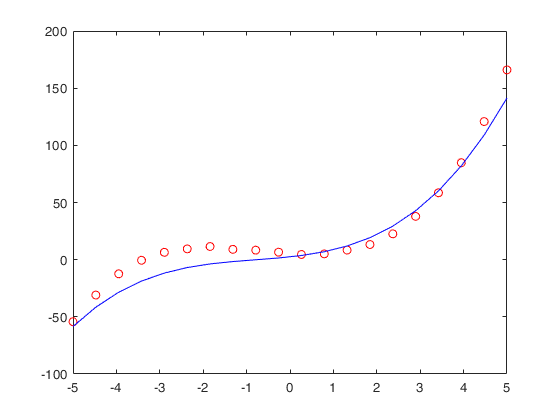

plot(x,y,"ro");
hold on;
plot(x,Polynomial_evaluation(x,w),"b-");
hold off;